% % Import the csv files to two matrices
% city_data = readtable('C:/Users/sangh/Desktop/Data Science/Project 1/city_data.csv');
% global_data = readtable('C:/Users/sangh/Desktop/Data Science/Project 1/global_data.csv');
% 
% city_data = table2array(city_data);
% global_data = table2array(global_data);

% % Compute moving averages across time for both the tables
% dim_city_data = size(city_data);
% dim_global_data = size(global_data);
% ma_city_data = city_data(:,2);
% ma_global_data = global_data(:,2);
% for ind = 5:1:dim_city_data(1)
%     temp_arr = ma_city_data(ind-4:ind,1);
%     num_el = sum(ones(size(temp_arr))-isnan(temp_arr));
%     temp_arr(isnan(temp_arr)) = 0;
%     ma_city_data(ind,1) = sum(temp_arr);
%     ma_city_data(ind,1) = ma_city_data(ind,1)/num_el;
% end
% 
% for ind = 5:1:dim_global_data(1)
%     temp_arr = ma_global_data(ind-4:ind,1);
%     num_el = sum(ones(size(temp_arr))-isnan(temp_arr));
%     temp_arr(isnan(temp_arr)) = 0;
%     ma_global_data(ind,1) = sum(temp_arr);
%     ma_global_data(ind,1) = ma_global_data(ind,1)/sum(ones(size(global_data(ind-4:ind,2)))-isnan(global_data(ind-4:ind,2)));
% end
% 
% ma_city_data(1:4,1) = [NaN NaN NaN NaN];
% ma_global_data(1:4,1) = [NaN NaN NaN NaN];
% city_data = [city_data ma_city_data];
% global_data = [global_data ma_global_data];

% % Convert arrays to table
% city_data = array2table(city_data,'VariableNames',{'Year','City Temperature','City Moving Average 5 years'});
% global_data = array2table(global_data,'VariableNames',{'Year','Global Temperature','Global Moving Average 5 years'});

% % Plot the data
% plot(city_data{:,1},city_data{:,3},'r'); 
% ylabel('Temperature moving average across 5 years (degrees Celsius)');
% xlabel('Year');
% xlim([1750 2015]);
% hold on
% plot(global_data{:,1},global_data{:,3},'b'); 
% legend('Pune City Data','Global Data','Location',"best")
% hold off


% Import the csv files to two matrices
city_data = readtable('C:/Users/sangh/Desktop/Data Science/Project 1/city_data.csv');
global_data = readtable('C:/Users/sangh/Desktop/Data Science/Project 1/global_data.csv');

city_data = table2array(city_data);
global_data = table2array(global_data);

% Compute moving averages across time for both the tables
dim_city_data = size(city_data);
dim_global_data = size(global_data);
ma_city_data = zeros(dim_city_data(1),1);
ma_global_data = zeros(dim_global_data(1),1);

for ind = 5:1:dim_city_data(1)
    temp_arr = city_data(ind-4:ind,2);
    num_el = sum(ones(size(temp_arr))-isnan(temp_arr));
    temp_arr(isnan(temp_arr)) = 0;
    ma_city_data(ind,1) = sum(temp_arr);
    ma_city_data(ind,1) = ma_city_data(ind,1)/num_el;
end

for ind = 5:1:dim_global_data(1)
    temp_arr = global_data(ind-4:ind,2);
    num_el = sum(ones(size(temp_arr))-isnan(temp_arr));
    temp_arr(isnan(temp_arr)) = 0;
    ma_global_data(ind,1) = sum(temp_arr);
    ma_global_data(ind,1) = ma_global_data(ind,1)/sum(ones(size(global_data(ind-4:ind,2)))-isnan(global_data(ind-4:ind,2)));
end

ma_city_data(1:4,1) = [NaN NaN NaN NaN];
ma_global_data(1:4,1) = [NaN NaN NaN NaN];

city_data = [city_data ma_city_data];
global_data = [global_data ma_global_data];

% Convert arrays to table
city_data = array2table(city_data,'VariableNames',{'Year','City Temperature','City Moving Average 5 years'});
global_data = array2table(global_data,'VariableNames',{'Year','Global Temperature','Global Moving Average 5 years'});

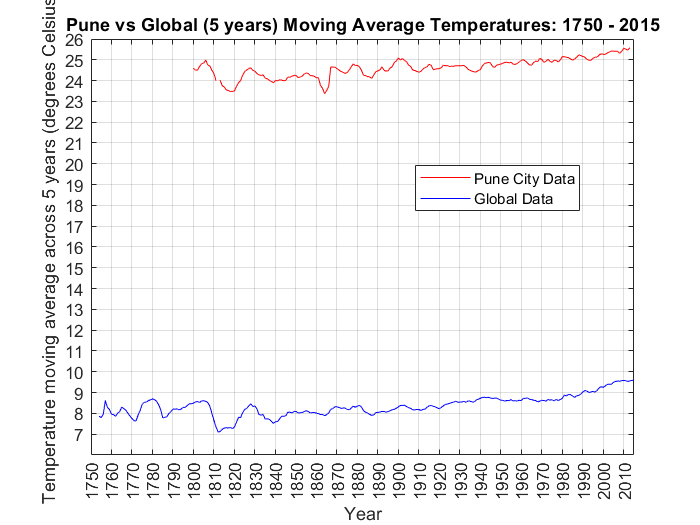

% Plot the data
plot(city_data{:,1},city_data{:,3},'r');
title("Pune vs Global (5 years) Moving Average Temperatures: 1750 - 2015");
ylabel('Temperature moving average across 5 years (degrees Celsius)');
xlabel('Year');
xlim([1750 2015])
xticks(1750:10:2015);
xtickangle(90);
yticks([7:1:26]);
grid on
hold on
plot(global_data{:,1},global_data{:,3},'b'); 
legend('Pune City Data','Global Data','Location',"best")
hold off